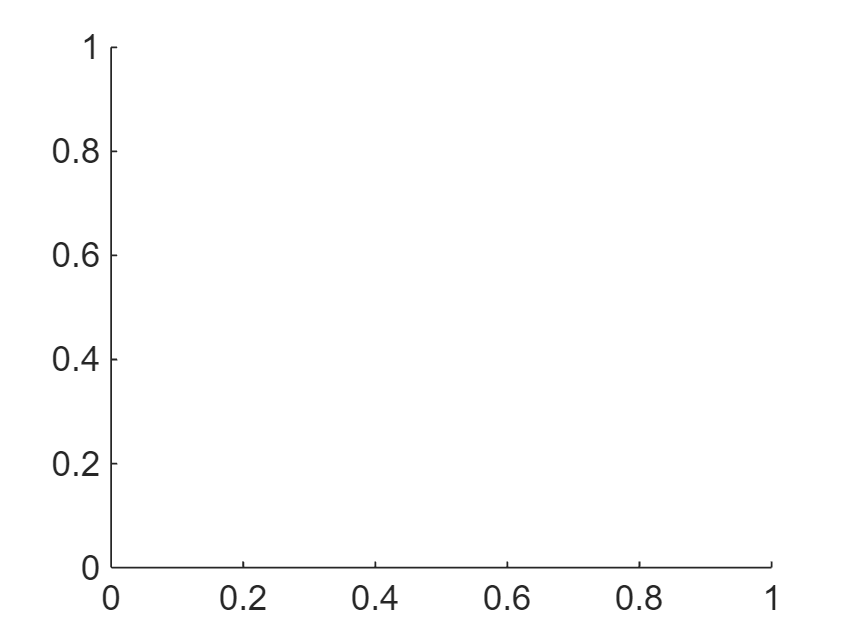


% ===== AUTHORS ===== %
% - Liam Murray
% - Sofia Simas
% - Lilly Mertzluft
% - Summer Chirpich
% - Satvik Kumar



% ===== INIT ========= %

[targetTime, targetPosX, targetPosY, targetPosZ] = generateTargetPath();
astrobee = generateAstrobeeStruct();



% ===== SIMULATE ===== %

thrustProfiles = solveThrustProfiles(targetTime, targetPosX, targetPosY, targetPosZ, astrobee);
hold on

plot(targetTime, thrustProfiles(1,:), 'r')
plot(targetTime, thrustProfiles(2,:), 'b')
axis on
hold off
[time, posX, posY, velX, velY, theta, omega] = solvePath(astrobee, thrustProfiles);



% ===== DISPLAY ===== %

% May be optional if drawnow is used in solvePath
renderAnimation(time, posX, posY, theta, thrustProfiles, astrobee); % Lilly

% We will also need to render the thrust too, we should create a function for this
% Consider using drawnow
% Liam

